BORRO TODO

clearvars;
close all;

CREO LAS MATRICES DE TRANSFORMACIÓN

syms alpha a theta d real
T=despZ(d)*rotZ(theta)*despX(a)*rotX(alpha);

di=[0.290 0 0 0.302 0 0.072];
ai=[0 0.270 0.070 0 0 0];
alphai=[-pi/2 0 -pi/2 pi/2 -pi/2 0];
syms q1 q2 q3 q4 q5 q6 real
qi=[q1 q2 q3 q4 q5 q6];

T01=subs(T,{a,alpha,d,theta},{ai(1),alphai(1),di(1),qi(1)});
T12=subs(T,{a,alpha,d,theta},{ai(2),alphai(2),di(2),qi(2)});
T23=subs(T,{a,alpha,d,theta},{ai(3),alphai(3),di(3),qi(3)});
T34=subs(T,{a,alpha,d,theta},{ai(4),alphai(4),di(4),qi(4)});
T45=subs(T,{a,alpha,d,theta},{ai(5),alphai(5),di(5),qi(5)});
T56=subs(T,{a,alpha,d,theta},{ai(6),alphai(6),di(6),qi(6)});


T02=simplify(T01*T12);
T03=simplify(T02*T23);
T04=simplify(T03*T34);
T05=simplify(T04*T45);
T06=simplify(T05*T56);


zL=[0 0 1]';
z0=zL;
z1 = T01(1:3,3);
z2 = T02(1:3,3);
z3 = T03(1:3,3);
z4 = T04(1:3,3);
z5 = T05(1:3,3);

CREO LOS JACOBIANOS

p0=[0 0 0]';
p1 = T01(1:3,4);
p2 = T02(1:3,4);
p3 = T03(1:3,4);
p4 = T04(1:3,4);
p5 = T05(1:3,4);
p6 = T06(1:3,4);


J1=simplify([cross(z0,(p6-p0));z0]);
J2=simplify([cross(z1,(p6-p1));z1]);
J3=simplify([cross(z2,(p6-p2));z2]);
J4=simplify([cross(z3,(p6-p3));z3]);
J5=simplify([cross(z4,(p6-p4));z4]);
J6=simplify([cross(z5,(p6-p5));z5]);

JPO=simplify([J1 J2 J3 J4 J5 J6]);

Obtener Interpolación en la Pose y la Velocidad en el Espacio Cartesiano

Ta=[1 0 0 -0.3; 0 -1 0 0.302; 0 0 -1 0.558; 0 0 0 1];
Tb=[1 0 0 0; 0 -1 0 0.302; 0 0 -1 0.358; 0 0 0 1];

initTime = 0;

% Distancia / Velocidad = Tiempo
toolSpeed=0.1; 
distance = norm(tform2trvec(Ta)-tform2trvec(Tb));
finalTime = (distance/toolSpeed)-initTime; 
timeStep=0.1;

% Esto devuelve un vetor formado por cada tiempo.
trajTimePoints = initTime:timeStep:finalTime; 
trajtInterval=[trajTimePoints(1); trajTimePoints(end)];


% Da las transformadas cada instante de tiempo T(:,:,i_tiempo)
% Da las velocidades en cada instante de tiempo Vel(:,i_tiempo)
[T, Vel] = transformtraj(Ta,Tb,trajtInterval,trajTimePoints); 

% Cambia las velocidades de orden para que este (posinción; orientación).
ve=[Vel(4:6,1); Vel(1:3,1)]; 

out_ws=0; 

MODELO CINEMÁTICO INVERSO

% Obtiene un vector q(i_tiempo,:) en el que la segunda columna son los valores de las articulaciones en cada instante de tiempo
for k=1:length(trajTimePoints)

    q(k,:)=IRB120_IK(T(:,:,k),ai,di,T03);

    if isinf(q(k,:)) 
        out_ws=1; 
    end
end

VELOCIDADES DE LAS ARTICULACIONES

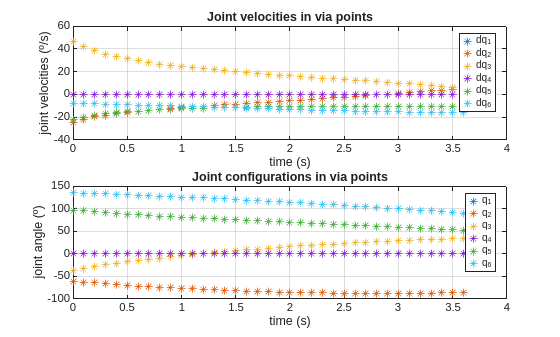

qd=[];
if out_ws==1
    disp('There is a position out of workspace');
else
    % Crea una matriz qd(i_tiempo, :) que da las velocidades de cada articulación en cada instante de tiempo
    for k=1:length(trajTimePoints)
        Jq=subs(JPO,{q1,q2,q3,q4,q5,q6},{q(k,1),q(k,2),q(k,3),q(k,4),q(k,5),q(k,6)});
        qd(:,k) = Jq\ve(:,k);
    end
        
    % Representamos las posiciones y las velocidades de las articulaciones en cada instante de tiempo
    figure;
    rg=180/pi; 

    subplot(2,1,1);
    plot(trajTimePoints,qd*rg, '*'); 
    xlabel('time (s)'); ylabel('joint velocities (º/s)');
    legend('dq_1','dq_2','dq_3','dq_4','dq_5','dq_6'); title('Joint velocities in via points'); grid;

    subplot(2,1,2);
    plot(trajTimePoints,q*rg, '*'); 
    xlabel('time (s)'); ylabel('joint angle (º)');
    legend('q_1','q_2','q_3','q_4','q_5','q_6'); title('Joint configurations in via points'); grid;
end

INTERPOLACIÓN

M = 100; % Numero de puntos en la interpolación

% Da una matriz QD(i_tiempo, :) en el que da las velocidades deseadas de las articulaciones en cada instante de tiempo.
QD = PointsVelCraig(q, trajTimePoints);

% Si había 37 puntos ahora habrá aproximadamente M veces más.
% TIME es un vector que da los nuevos tiempos interpolados entre cada instante de tiempo anterior
% QS[i_tiempo, :] son las posiciones nuevas de las articulaciones en cada instante de tiempo
[QS, TIME] = CubicSpline_Interp(q, QD, trajTimePoints, M);

REPRESENTACIÓN DE LA INTERPOLACIÓN

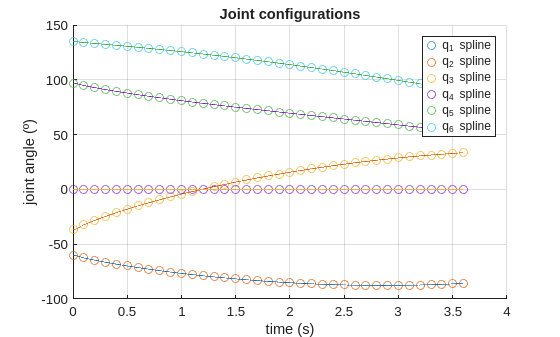

% POSICIÓN
figure;
hold on
plot(trajTimePoints,q*rg, 'o');
legend('q_1','q_2','q_3','q_4','q_5','q_6'); 
plot(TIME,QS*rg); 
legend('q_1 spline','q_2 spline','q_3 spline','q_4 spline','q_5 spline','q_6 spline'); 
title('Joint configurations'); grid;
xlabel('time (s)'); ylabel('joint angle (º)');
hold off

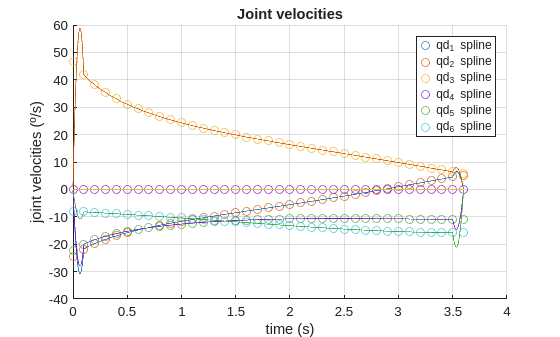

% VELOCIDAD
% Derivar QS
D_QS = diff(QS);
D_TIME = diff(TIME); % Es constante debido a que la deferencia entre cada instante de tiempo es la misma.
D_QS = D_QS/D_TIME(1);
D_QS = [D_QS;zeros(1,6)]; % Mismo tamaño que TIME. Vel = 0 al final

figure;
hold on
plot(trajTimePoints,qd*rg, 'o');
legend('qd_1','qd_2','qd_3','qd_4','qd_5','qd_6'); 
plot(TIME,D_QS*rg); 
legend('qd_1 spline','qd_2 spline','qd_3 spline','qd_4 spline','qd_5 spline','qd_6 spline'); 
title('Joint velocities'); grid;
xlabel('time (s)'); ylabel('joint velocities (º/s)');
hold off

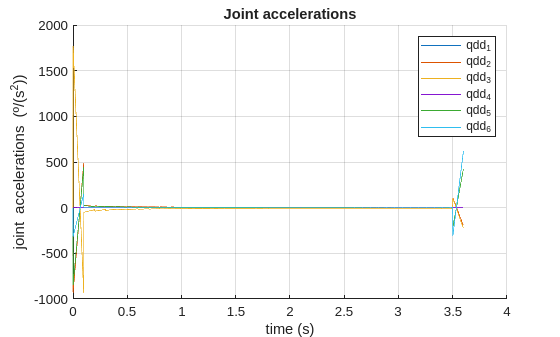

% ACELERACIÓN

% Derivar DQS
DD_QS = diff(D_QS(1:end-1,:)); % Quito los ceros añadidos anteriormente
DD_QS = DD_QS/D_TIME(1);
DD_QS = [zeros(1,6); DD_QS]; % Tamaño menor a TIME. Accel = 0 al principio

figure;
hold on
plot(TIME(1:end-1),DD_QS*rg);
legend('qdd_1','qdd_2', 'qdd_3', 'qdd_4', 'qdd_5', 'qdd_6'); 
title('Joint accelerations'); grid;
xlabel('time (s)'); ylabel('joint accelerations (º/(s^2))');
hold off

EFECTOR FINAL

% POSICIÓN
X = p6(1);
Y = p6(2);
Z = p6(3);

L = length(QS);
x_vec = zeros(L,1);
y_vec = ones(L,1);
z_vec = zeros(L,1);
y_ref = y_vec*0.302; % Y target

% Evaluo las variables simbólicas y creo vectores "x(i_tiempo)", "y(i_tiempo)", y "z(i_tiempo)" que muestran 
% la posición del efector final en cada instante de tiempo
for k=1:L
    x_vec(k) = subs(X,{q1,q2,q3,q4,q5,q6},{QS(k,1),QS(k,2),QS(k,3),QS(k,4),QS(k,5),QS(k,6)});
    y_vec(k) = subs(Y,{q1,q2,q3,q4,q5,q6},{QS(k,1),QS(k,2),QS(k,3),QS(k,4),QS(k,5),QS(k,6)});
    z_vec(k) = subs(Z,{q1,q2,q3,q4,q5,q6},{QS(k,1),QS(k,2),QS(k,3),QS(k,4),QS(k,5),QS(k,6)});
end

REPRESENTACIÓN EFECTOR FINAL

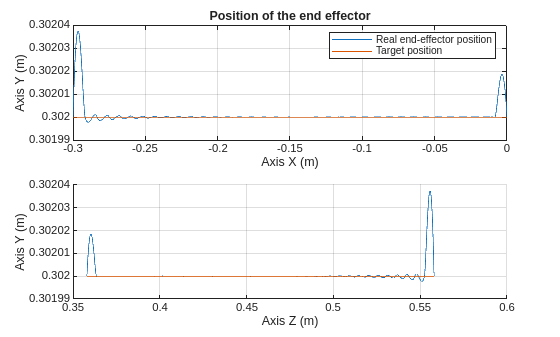

figure;

subplot(2,1,1);
plot(x_vec, y_vec); 

hold on

plot(x_vec, y_ref); 
legend('Real end-effector position', 'Target position');
title('Position of the end effector'); grid;
xlabel('Axis X (m)'); ylabel('Axis Y (m)');

hold off

subplot(2,1,2);

hold on

plot(z_vec, y_vec); 
plot(z_vec, y_ref); 
xlabel('Axis Z (m)'); ylabel('Axis Y (m)');grid;

hold off

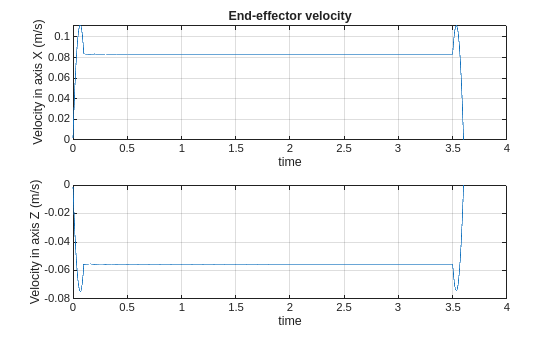

% VELOCIDAD
% Utilizo en jacobiano con el fin de obtener las velocidades en cada instante de tiempo del efector final

v_vec = zeros(L,6);
for k=1:L
    J = subs(JPO,{q1,q2,q3,q4,q5,q6},{QS(k,1),QS(k,2),QS(k,3),QS(k,4),QS(k,5),QS(k,6)});
    v_vec(k,:) = (J*D_QS(k,:)')';
end

figure;

subplot(2,1,1);

plot(TIME, v_vec(:,1)); 
title('End-effector velocity'); grid;
xlabel('time'); ylabel('Velocity in axis X (m/s)');

subplot(2,1,2);

plot(TIME, v_vec(:,3)); grid;
xlabel('time'); ylabel('Velocity in axis Z (m/s)');

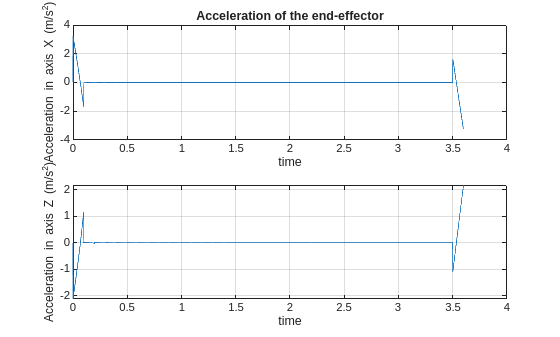

% ACCELERATION
% Utilizo la diferenciación con el fin de obtener las aceleraciones en cada instante de tiempo del efector final
a_vec = diff(v_vec);
a_vec = a_vec/D_TIME(1);
a_vec = [zeros(1,6);a_vec];
a_vec = a_vec(1:end-1,:);

figure;

subplot(2,1,1);

plot(TIME(1:end-1), a_vec(:,1)); 
title('Acceleration of the end-effector'); grid;
xlabel('time'); ylabel('Acceleration in axis X (m/s^2)');

subplot(2,1,2);

plot(TIME(1:end-1), a_vec(:,3)); grid;
xlabel('time'); ylabel('Acceleration in axis Z (m/s^2)');

FUNCIONES DADAS 

% CRAIG
function qd = PointsVelCraig(q,t)
% Computing joint velocities of via points using Craig criteria.
% Input data size
    num_joints=size(q,2); num_points=size(q,1);
    % Zero initialization of joint velocities
    qd=zeros(size(q));
    for j=1:num_joints
        for i=2:num_points-1
            if (sign(q(i,j)-q(i-1,j))~=sign(q(i+1,j)-q(i,j))) && (q(i-1,j)==q(i,j)) && (q(i,j)==q(i+1,j))
                qd(i,j)=0;
            else
                qd(i,j) = (1/2)*((q(i+1,j)-q(i,j))/(t(i+1)-t(i))+ (q(i,j)-q(i-1,j))/(t(i)-t(i-1)));
            end
        end
    end
end

% SPLINE
function [qs,time] = CubicSpline_Interp(q,qd,t,M)
    % Interpolation using cubic spline
    L=length(q);
    time=0;
    qs=q(1,:); % first joint configuration
    for i=1:L-1
        T=t(i+1)-t(i);
        a=q(i,:);
        b= qd(i,:);
        c = (3/T^2)*(q(i+1,:)-q(i,:))-(1/T)*(qd(i+1,:)+2*qd(i,:));
        d = (-2/T^3)*(q(i+1,:)-q(i,:))+(1/T^2)*(qd(i+1,:)+qd(i,:));
        
        temp=linspace(t(i),t(i+1),M);
        temp=temp(2:M);
        time=[time,temp];

        for k=1:M-1
            qtemp(k,:)=a+b*(temp(k)-t(i))+c*(temp(k)-t(i))^2+d*(temp(k)-t(i))^3;
        end
        qs=[qs;qtemp];
    end
end